# 傅里叶变换

## 二维扭曲和旋转

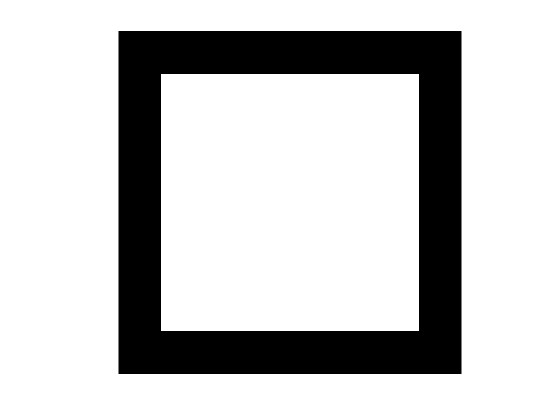

% 建立正方形矩阵
M = 256;% 矩阵高度
N2 = 256;% 矩阵宽度
S0 = zeros(M,N2);
S0(M/8+1:M*7/8,N2/8+1:N2*7/8) = 1;

S0_ff = fftshift(fft2(fftshift(S0)));
S0_ff = abs(S0_ff);
S0_ff = S0_ff./max(max(S0_ff));
S0_ff = 20*log10(S0_ff+1e-4);

figure
imagesc(S0);colormap gray% 预定义的颜色图
axis off image% 不显示图中的坐标轴

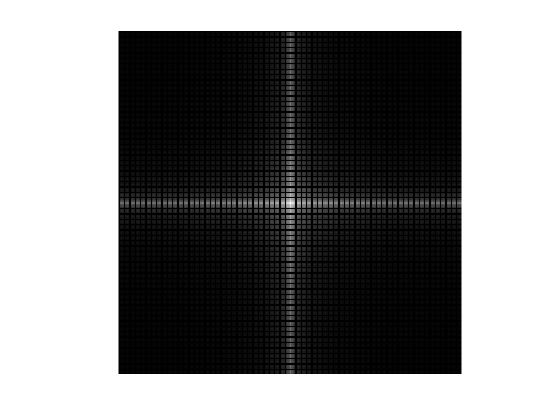

% colormap parula
% colormap jet
% colormap hot
% colormap cool
% colormap spring
% colormap summer
% colormap autumn
% colormap winter
% ...

figure
imagesc(S0_ff);colormap gray
axis off image

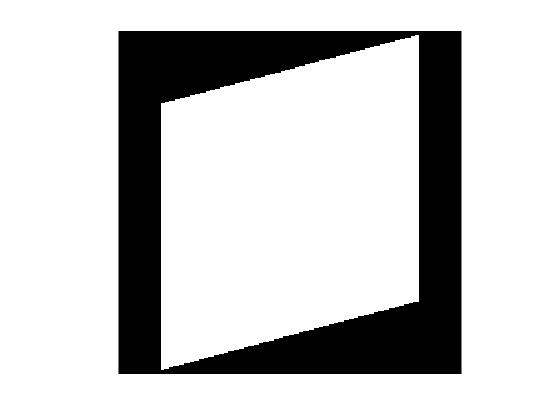


% 扭曲信号
S1 = zeros(M,N2);
theta = -pi/12;
for ii = 1:M
    for jj = 1:N2
        x = jj-N2/2;
        y = ii-M/2;
        At = [1 0; sin(-theta) cos(-theta)]*[x y].';
        xx = round(At(1,1)+N2/2);
        yy = round(At(2,1)+M/2);
        % xx = round(x+N/2);
        % yy = round(x*sin(-theta)+y*cos(-theta)+M/2);
        if(xx>=1 && xx<= N2 && yy>=1 && yy<=N2)
            S1(ii,jj) = S0(yy,xx);
        end
    end
end

S1_ff = fftshift(fft2(fftshift(S1)));
S1_ff = abs(S1_ff);
S1_ff = S1_ff./max(max(S1_ff));
S1_ff = 20*log10(S1_ff+1e-4);

figure
imagesc(S1);colormap gray
axis off image

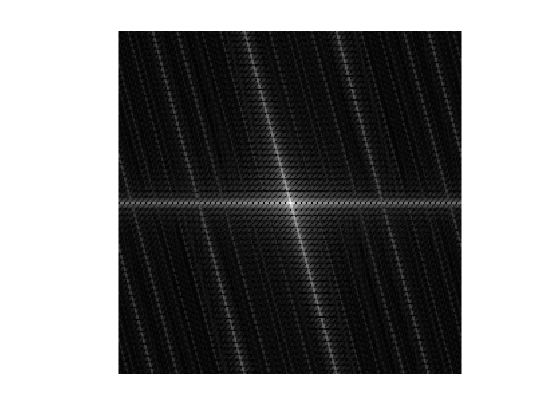


figure
imagesc(S1_ff);colormap gray
axis off image

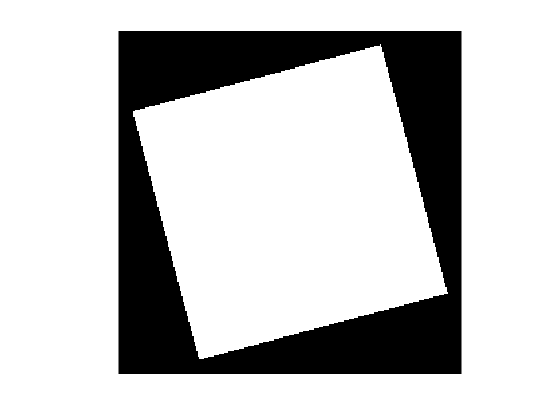


% 旋转信号
S2 = zeros(M,N2);
for ii = 1:M
    for jj = 1:N2
        x = jj-N2/2;
        y = ii-M/2;
        At = [cos(-theta) -sin(-theta); sin(-theta) cos(-theta)]*[x y].';
        xx = round(At(1,1)+N2/2);
        yy = round(At(2,1)+M/2);
        % xx = round(x*cos(-theta)-y*sin(-theta)+N/2);
        % yy = round(x*sin(-theta)+y*cos(-theta)+M/2);
        if(xx>=1 && xx<= N2 && yy>=1 && yy<=N2)
            S2(ii,jj) = S0(yy,xx);
        end
    end
end

S2_ff = fftshift(fft2(fftshift(S2)));
S2_ff = abs(S2_ff);
S2_ff = S2_ff./max(max(S2_ff));
S2_ff = 20*log10(S2_ff+1e-4);

figure
imagesc(S2);colormap gray
axis off image

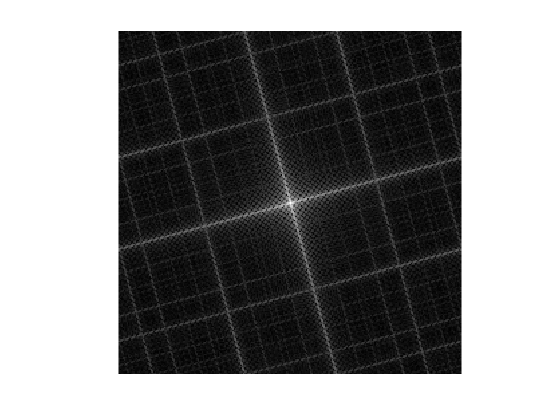


figure
imagesc(S2_ff);colormap gray
axis off image

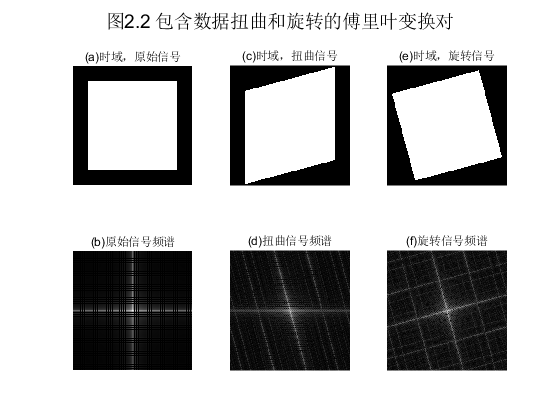


figure;colormap gray
subplot(2,3,1),imagesc(S0);axis off image
title('(a)时域，原始信号')
subplot(2,3,4),imagesc(S0_ff);axis off image
title('(b)原始信号频谱')
subplot(2,3,2),imagesc(S1);axis off image
title('(c)时域，扭曲信号')
subplot(2,3,5),imagesc(S1_ff);axis off image
title('(d)扭曲信号频谱')
subplot(2,3,3),imagesc(S2);axis off image
title('(e)时域，旋转信号')
subplot(2,3,6),imagesc(S2_ff);axis off image
title('(f)旋转信号频谱')
suptitle('图2.2 包含数据扭曲和旋转的傅里叶变换对')

说明：矩阵旋转和矩阵扭曲的思路相同，先转换到以原点为中心的矩阵，然后利用转换矩阵转换，转换后平移回原位置，最后赋值计算。

## 傅里叶变换示例

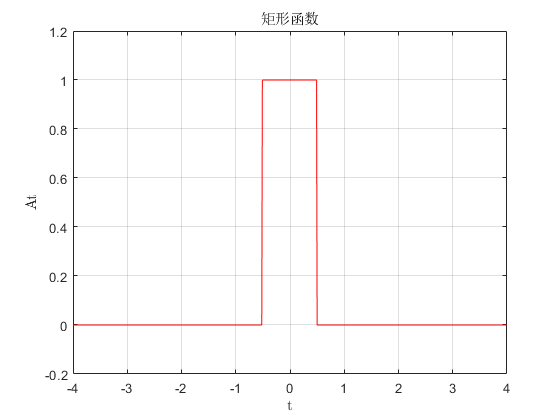

% 矩形函数及其傅里叶变换
dt1 = 0.01;
t1 = -100:dt1:100-dt1;

% 确定T的范围
At = zeros(1,20000);
for i = 9950:1:10050
    At(i) = 1;
end

figure
plot(t1,At,'r')
title('矩形函数'),xlabel('t','Interpreter','latex'),ylabel('At','Interpreter','latex')
axis([-4 4, -0.2 1.2])
grid on

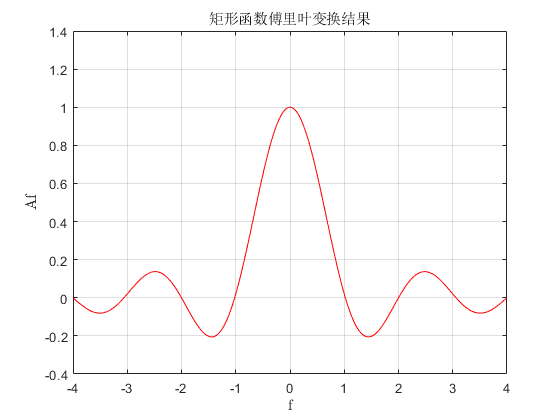


N1 = 2^14;
df1 = 1/dt1;
f1 = -df1/2:df1/N1:(df1/2-df1/N1);
Af = fft(fftshift(At),N1);
Af = real(Af)/max(real(Af));

figure
plot(f1,fftshift(Af),'r')
title('矩形函数傅里叶变换结果'),xlabel('f','Interpreter','latex'),ylabel('Af','Interpreter','latex')
axis([-4 4, -0.4 1.4])
grid on

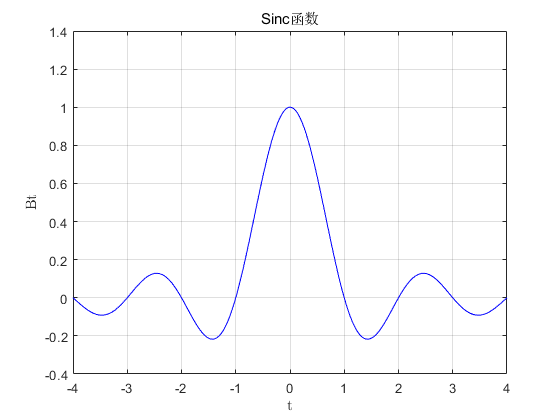


% Sinc函数及其傅里叶变换
dt2 = 0.01;
t2 = -100:dt2:100-dt2;

Bt = sin(pi*t2)./(pi*t2);
Bt(10001) = 1;

figure
plot(t2,Bt,'b')
title('Sinc函数'),xlabel('t','Interpreter','latex'),ylabel('Bt','Interpreter','latex')
axis([-4 4, -0.4 1.4])
grid on

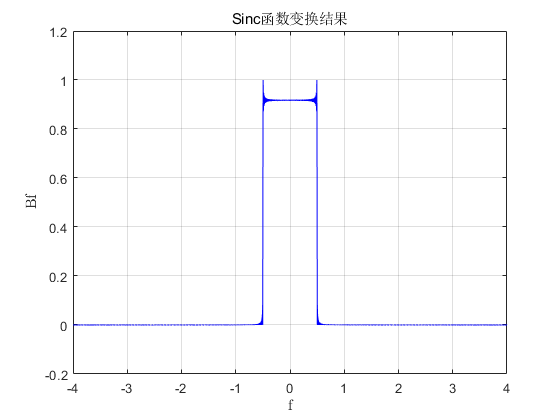


N2 = 2^20;
df2 = 1/dt2;
f = -df2/2:df2/N2:(df2/2-df2/N2);
Bf = fft(Bt,N2);
Bf = abs(Bf)/max(abs(Bf));

figure
plot(f,fftshift(Bf),'b')
title('Sinc函数变换结果'),xlabel('f','Interpreter','latex'),ylabel('Bf','Interpreter','latex')
axis([-4 4, -0.2 1.2])
grid on

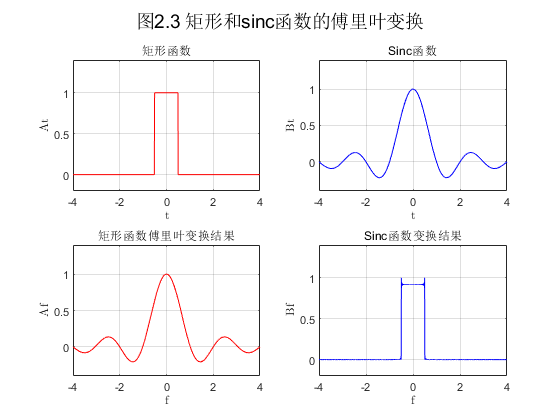


% 绘图
figure
subplot(221),plot(t1,At,'r')
title('矩形函数'),xlabel('t','Interpreter','latex'),ylabel('At','Interpreter','latex')
axis([-4 4, -0.2 1.4])
grid on

subplot(223),plot(f1,fftshift(Af),'r')
title('矩形函数傅里叶变换结果'),xlabel('f','Interpreter','latex'),ylabel('Af','Interpreter','latex')
axis([-4 4, -0.4 1.4])
grid on

subplot(222),plot(t2,Bt,'b')
title('Sinc函数'),xlabel('t','Interpreter','latex'),ylabel('Bt','Interpreter','latex')
axis([-4 4, -0.4 1.4])
grid on

subplot(224),plot(f,fftshift(Bf),'b')
title('Sinc函数变换结果'),xlabel('f','Interpreter','latex'),ylabel('Bf','Interpreter','latex')
axis([-4 4, -0.2 1.4])
grid on

suptitle('图2.3 矩形和sinc函数的傅里叶变换')